# Pendulum Linear ID

load('chirp2.mat')
y1 = angular_velocity.data;
y2 = pendulum_angle.data;

y1 = y1(2:end);
y2 = y2(2:end);
u = u(2:end);
N = length(y1);
y = zeros(2*N,1);
for i = 1:N
    y((i-1)*2+1:i*2) = [y1(i); y2(i)];
end

x0 = [y1(1);y2(1);(y2(2)-y2(1))/h];

a2_0 = 0.01;

theta = a2_0;
lambda = 0.01;
maxiter = 2000;
p = 1;
h = 0.01;
converged = false;
maxiter_reached = false;
iter = 1;

B = [a5*h; 0; 0];
C = [1 0 0; 0 1 0];
D = [0; 0];

while ~converged && ~maxiter_reached 

    [Abar] = theta2matrices(theta, h, a1, a3, a4);
    [yhat, xhat] = simsystem(Abar, B, C, x0, u);
    E = y - yhat;
    psi = psi_fun(xhat, x0, Abar, h);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;
    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end

A = Abar;
a2 = theta(1);

## Validation

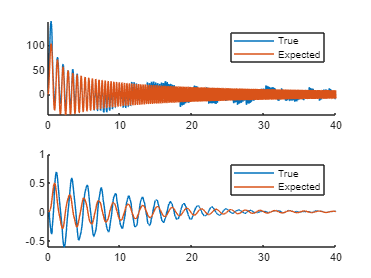

t = 0:h:(length(u)*h)-h;
[yhat,xhat] = simsystem(A, B, C, x0, u);
y1hat = yhat(1:2:end);
y2hat = yhat(2:2:end);
figure;
tiledlayout(1,2);
title("Identification Comparison")
nexttile;
hold on
plot(t,y1);
plot(t,y1hat);
legend("True", "Expected")
nexttile
hold on
plot(t,y2);
plot(t,y2hat);
legend("True", "Expected")

## Verification data

% A(3,1) = A(3,1)*0.9;
load('chirp.mat')
t = 0:h:(length(u)*h)-h;
y1 = angular_velocity.data;
y2 = pendulum_angle.data;
y1 = y1(2:end);
y2 = y2(2:end);
[yhat,xhat] = simsystem(A,B,C,[y1(1), y2(1), 0.9*(y2(2)-y2(1))/h], u);

Error using simsystem
Too many input arguments.

y1hat = yhat(1:2:end); y2hat = yhat(2:2:end);

figure;
tiledlayout(1,2);
title("Verification Comparison")
nexttile
hold on
plot(0:h:(length(y1)*h-h),y1);
plot(t,y1hat);
legend("True", 'Expected');
nexttile
hold on
plot(0:h:(length(y2)*h-h),y2);
plot(t,y2hat);
legend("True", 'Expected');

% VAF = 

## Functions

function [Abar,x0] = theta2matrices(theta,h, a1, a3, a4)

a2 = theta(1);

Abar=[1-a1*h 0 0; 0 1 h; a2*h -a3*h 1-a4*h]; 
end

function psi = psi_fun(xhat, x0, Abar,h)

C = [1 0 0; 0 1 0];
% Dimensions
n = 3; l = 2;

% Derivative Definitions
dAbar1 = [0 0 0; 0 0 0; h 0 0];

N = size(xhat,2); 
p = 1; % 11 sub-parameters of theta
% xhat = xhat'; % x coming in is Nxn, now is nxN

dx = zeros(n,p);
dy = zeros(l,p);
psi = zeros((N-1)*l,p);

% First iteration
dx1 = dAbar1*x0;

dx=dx1;
for k = 2:N % xhat is 0 - N-1, 
    % dy / psi update
    for i = 1 : p
        dy(:,i) = C * dx(:,i);
    end
    psi((k-2)*l+1:(k-1)*l,:) = -dy;

    % dx update
    % A parameters
    dx(:,1) = Abar * dx(:,1) + dAbar1 * xhat(:,k);

end
 psi = [zeros(2,p) ; psi]; % How to deal with dyhat0?
end
